% MATLAB program to demonstrate image negative transformation
% Insert a color input image using imread function
input_image = imread('20250119_134256.JPG');

% Find the negative of the input image
negative_image = 255 - input_image;

% Display the original image and negative image
subplot(1, 2, 1), imshow(input_image), title('Original Image')
subplot(1, 2, 2), imshow(negative_image), title('Negative Image')

% Save the negative image in jpg format
imwrite(negative_image, 'negative_image.jpg');

% Log Transformation
% Convert the image to double datatype for calculations
input_image = im2double(input_image);

% Constant to determine the nature of the log curve
c = 1;

% Perform the log transformation
log_transformed = c * log(1 + input_image);

% Display the original image and log-transformed image
subplot(1, 2, 1), imshow(input_image), title('Original Image')
subplot(1, 2, 2), imshow(log_transformed), title('Log-Transformed Image')

% Save the log-transformed image
imwrite(log_transformed, 'log_transformed_image.jpg');

% Power Law Transformation
%  Set a desired gamma value for the power law transformation
gamma = 0.4;

% Perform the power law transformation of image
power_law_image = input_image .^ gamma;

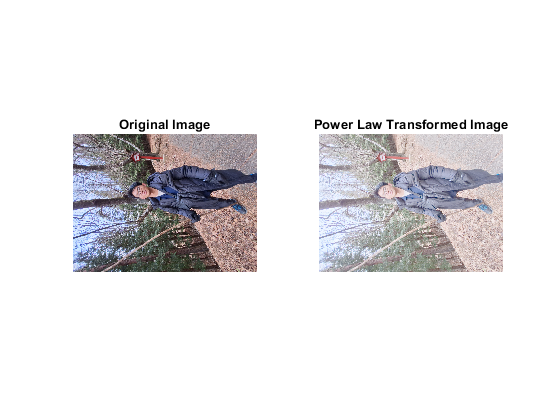

% Display the original and power law transformed images
subplot(1, 2, 1), imshow(input_image), title('Original Image')
subplot(1, 2, 2), imshow(power_law_image), title('Power Law Transformed Image')

% Save the power law transformed image
imwrite(power_law_image, 'power_law_transformed_image.jpg');


